%links to communicating to arduino
%https://www.mathworks.com/matlabcentral/answers/56706-how-to-send-data-from-matlab-to-arduino-an
%https://www.mathworks.com/help/supportpkg/arduino/ref/transmit-receive-data-can-blocks.html


Import SS and Convert to DT

clear;

%system dynamics

m_pend = 0.312;     %kg
m_cart = 0.493;     %kg
I_pend = 0.00024;   %kg*m^2
l = 0.04;           %from rotation point to COM
g = 9.8;            %m/s^2
f = 0.01;           %frictional coefficient --make this higher???
K_T = 0.11;         %N*m/A
R_motor = 10;       %ohm
r_wheel = 0.0335;   %m


% SS matrices

A21 = -(I_pend+m_pend*l^2)*f / (I_pend*(m_cart + m_pend)+m_cart*m_pend*l^2);
A22 = (m_pend^2*g*l^2) / (I_pend*(m_cart+m_pend)+m_cart*m_pend*l^2);
A41 = (-m_pend*l*f) / (I_pend*(m_cart+m_pend)+m_cart*m_pend*l^2);
A42 = (m_pend*g*l*(m_cart+m_pend)) / (I_pend*(m_cart+m_pend)+m_cart*m_pend*l^2);

A = [ 0 1 0 0;
    0 A21 A22 0;
    0 0 0 1;
    0 A41 A42 0];

B2 = (I_pend+m_pend*l^2)/(I_pend*(m_cart+m_pend)+m_cart*m_pend*l^2);
B4 = (m_pend*l) / (I_pend*(m_cart+m_pend)+(m_cart*m_pend*l^2));

B = [0;
    B2;
    0
    B4];

C = [1 0 0 0;
    0 0 1 0];

D = [0;
    0];

%create SS and TF model

ts = 0.005; %s

sys_cont = ss(A,B,C,D);
sys_disc = c2d(sys_cont,ts);

%[num,denom] = ss2tf(A,B,C,D); %implicit ZoH
%sys_tf = [num, denom];

A = sys_disc.A; B = sys_disc.B; C = sys_disc.C; D = sys_disc.D;

Define MPC Parameters

R = .1;  %why do we need to make this high for decent performance?
%Q = diag([.1, 20]); % 2x2 b/c weighting output not states
Q = diag([100,100]);
N = 100;%8; %prediction horizon (and control horizon)

Compute/Initialize Lifted Form Matrices

Qbar = [];
Rbar = [];
CAB = [];
Sx = [];
Su = zeros(N*size(C,1),N);
for ii = 1:N
    Qbar = blkdiag(Qbar,Q);
    Rbar = blkdiag(Rbar,R);
    Sx = [Sx;C*A^ii];
    CAB = [CAB,C*A^(ii-1)*B];
end
CAB = reshape(CAB,[1,2*size(CAB,2)])';
for ii = 1:N
    Su(:,ii) = [zeros(2*ii,1);CAB(1:2*N-2*ii)];
end
 
Su1 = Su(:,1);

Convert Lifted form to QP form -- Precompute components of F

LL = tril(ones(N));
H = 2*(Rbar+Su'*Qbar*Su);
H = (H + H')/2; %to get rid of hessian not symmetric warning
Fr = -2*(Qbar*Su)';
Fx = 2*(Sx'*Qbar*Su)';

%calculate motor saturation region based on 12V max
u_max = 2*K_T/R_motor/r_wheel * 7;
u_min = -2*K_T/R_motor/r_wheel * 7;

Define constraints

G = [eye(N);-eye(N)]; %output constraints
W = u_max*ones(2*N,1);  %here is where we set motor limits (input force limits!)
S = zeros(2*N,4); %slack on outputs constraints

Define Initial Conditions

X = [0 ;0 ;pi/6 ;0];
T = 3000;
time_step = 0.005;
time = 1:time_step:T*time_step+1;
freq = 1/10; % (Hz)
sq_wav = (pi/24)*square(2*pi*freq*time,50); % 50% duty cycle
impulse = -8;

r = [zeros(1,length(sq_wav)); zeros(1,length(sq_wav))]; % reference traj (4xT+N+1)
r2 = reshape(r, [1,length(r)*2]);

%Z = zeros(2,1); % not sure why this is a 2x1
U = 0;
options = optimoptions('quadprog');
options.Display = 'none';
options.Display = 'off';

Solve the QP at every timestep for T steps

for ii = 1:T-1
    Xact(ii,:) = X; %For graphing
    f = Fx*X+Fr*r2(ii:ii+2*N-1)'; 
    Z = quadprog(H,f,G,W+S*X,[],[],[],[],[],options);  %Here is the magic!
    %Z = -inv(H)*f;
    Ypredict = Sx*X+Su*Z;
    Uopt(ii) = Z(1);  %Just use the first item   
    %Uopt(ii) = min(u_max,max(u_min, Uopt(ii)));  %add motor saturation!
    U = Uopt(ii);
    X = A*X+B*U;
    if ii == 1500 %|| ii == 1500%mod(ii,400) == 0
        X = X + [0;0;0;impulse];
        impulse = -impulse;
    end
%     if ii == 1000
%         X = X + [0;0;0;impulse];
%         impulse = -impulse;
%     end
end 
Xact(ii+1,:) = X;

Plot MPC

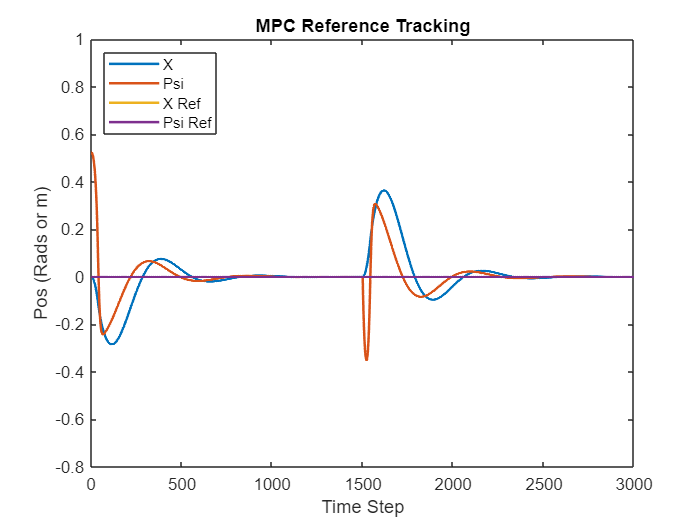

r2plot = r2;
figure(1)
plot([1:T],Xact(:,1), [1:T],Xact(:,3),[1:T],r2plot(1,1:T), [1:T],zeros(1,T), 'LineWidth',1.5);
ylim([-.8,1]);
xlabel("Time Step");
ylabel("Pos (Rads or m)");
title("MPC Reference Tracking")
legend("X", "Psi", "X Ref", "Psi Ref", 'Location', 'northwest')

Plot LQR Input Force

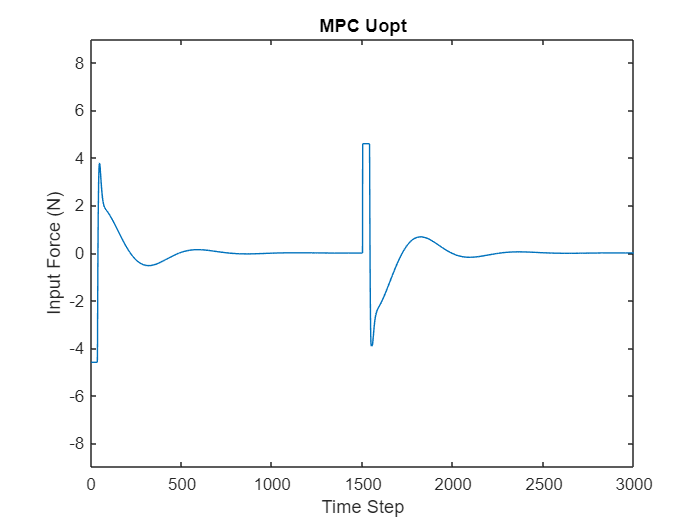

figure(2)
plot(Uopt)
ylim([-9,9]);
xlabel("Time Step");
ylabel("Input Force (N)");
title("MPC Uopt")

Plot LQR Motor Voltage

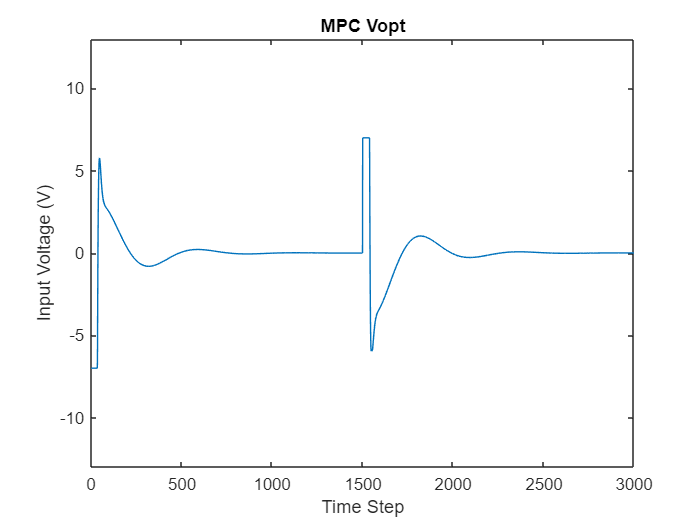

voltage_motors = Uopt * (R_motor * r_wheel / 2 / K_T);
figure(3)
plot(voltage_motors)
ylim([-13,13]);
xlabel("Time Step");
ylabel("Input Voltage (V)");
title("MPC Vopt")